# **BONE RUGOSITY ANALYSIS**

The roughness of a bone interface is characterized by the Root Mean Square (RMS) of the height of the rugosity at the endosteum of the bone, noted as Rq, and the correlation length, which characterizes the roughness horizontally.

This script enables the computation of the RMS for a bone. The height is computed relative to a parabola that fits the boundary of the bone. The images used are X-ray images of slices from five ex-vivo bones.

%% Create bone structure 
% bones = {{'227G' 1270 1793}; {'245D' 470 1861}; {'251G' 761 2125}; {'271G' 1590 2954}};
bones = {'271G' '267G' '251G' '245D' '227G'};
min_slices = [1270 0 470 761 1590];
max_slices = [1793 0 1861 2125 2954];
T = table(min_slices', max_slices', 'VariableNames', {'min_slice', 'max_slice'}, 'RowNames', bones);

% Get bone

`Select the bone : `

bone = '227G';
dirname = ['~/Documents/BoneRugosity/RMS/', bone, '/'];

min_slice = T{bone, 'min_slice'};
max_slice = T{bone, 'max_slice'};

`Select the slice :`

num_slice = 1590;

file = ['SAMPLE_', bone, '_SLICE_', int2str(num_slice), '.bmp']; 
filename = [dirname, file];

% LOAD IMAGE OF THE SLICE
bone_bmp = imread(filename); 

% THRESHOLD TO CONVERT TO BINARY IMAGE
threshold = graythresh(bone_bmp);                   % Find an automatic threshold
binary_image = imbinarize(bone_bmp, threshold);

### COMPUTATION OF THE RMS

The image is binarize with an automatic threshold. Then, in order to obtain the heigth of the porosity of the endosteum, the boundary is obtained using the bwboundaries function. We then process the data to obtain only the endosteum boundary and remove the outlier.  

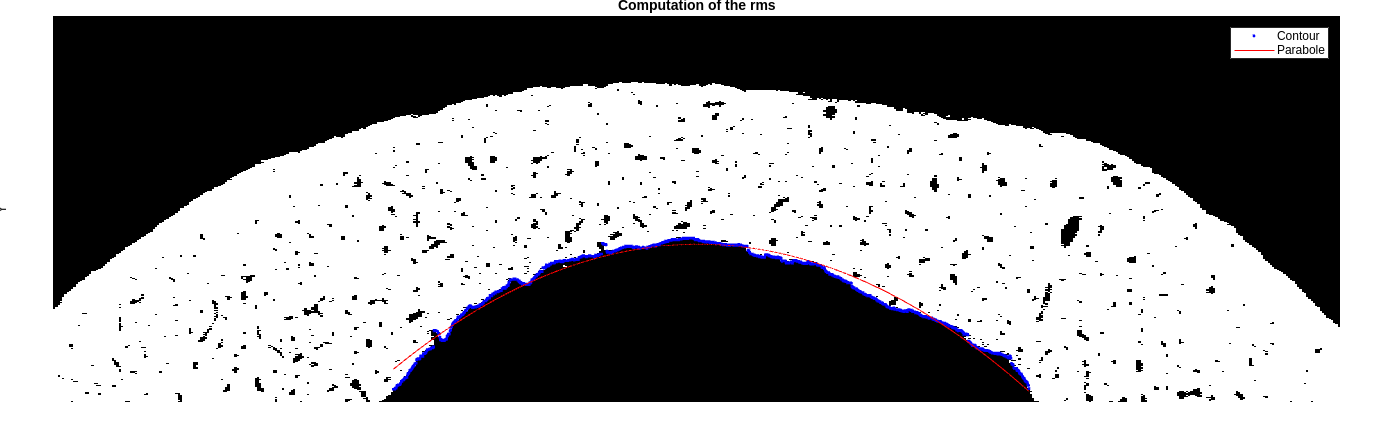

% Compute the boundary of the endost
boundary_endost = ExtractBoundary(binary_image);

% Fit a parabola to the boundary
surface = FitParabola(boundary_endost);

% Computation of rms 
rq = rms(surface(:, 2) - boundary_endost(:, 2))*9e-3;       % Rms (mm) - Pixel size = 9e-3 mm

% Plot the result 
figure
imshow(binary_image);
hold on;
plot(boundary_endost(:, 1), boundary_endost(:, 2), 'b.');  % Trace le contour
hold on;
plot(boundary_endost(:, 1), surface(:, 2), 'r-');  % Trace la parabole ajustée
xlabel('X');
ylabel('Y');
legend('Contour', 'Parabole');
title('Computation of the rms'); hold off;

format = 'The rms value is Rq = %.4f mm';
fprintf(format, rq);

The rms value is Rq = 0.1192 mm